# PRÁCTICA 5: Suavizado y Realce

## AÑADIR RUIDO A UNA IMAGEN

- tipo de ruido: 'gaussian', 'salt & pepper' …

- <p1>... : parámetros

## FILTROS ESPACIALES

- tipo: ‘gaussian’, ‘average’, ‘disk’, …

- <p1>... : parámetros

#### EJERCICIOS 1

Cargue la imagen ‘patron0.jpg’ (im1), genere la imagen im2 añadiéndole a ésta un ruido gaussiano de media cero y varianza 0.001. Muestre en una figura ambas imágenes y sus histogramas, subplot (2,2,…).

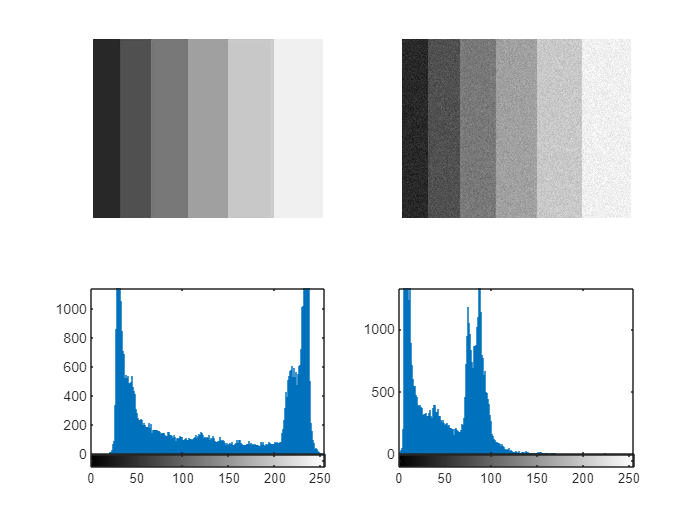

clear;
im1 = imread('patron0.jpg');
im2 = imnoise(im1, 'gaussian', 0, 0.001);
im1h = imhist(im1);
im2h=imhist(im2);

figure(1);
subplot(2,2,1); imshow(im1); % , title("Imagen original"));
subplot(2,2,2); imshow(im2); % , title("Con ruido gaussiano"));

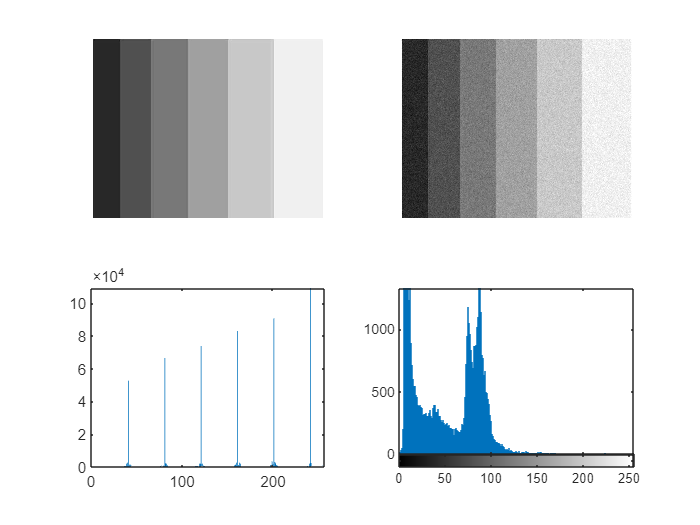

subplot(2,2,3); bar(im1h); %imshimhist(im1);

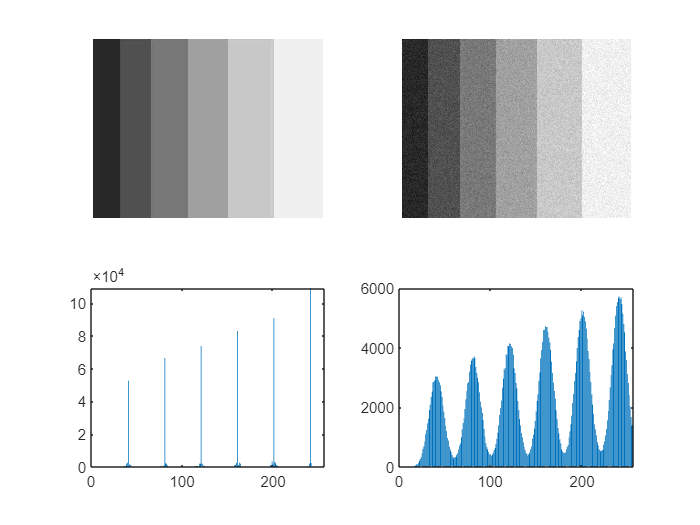

subplot(2,2,4); bar(im2h); %imhist(im1r);

im1(1: 20, 1:10)

ans = 20×10 uint8 matrix
   246   250   255   244   255   242   255   241   255   255
   253    53    13    25    52    27    29    37    36    36
   255    21    48    58    43    33    32    60    46    46
   250    21    52    37    26    47    40    42    42    42
   255    44    36    32    43    43    34    39    42    42
   222    41    37    36    45    30    32    43    40    40
   255    58    43    26    37    49    48    38    43    43
   255    29    49    49    38    38    34    41    41    41
   254    42    46    38    40    44    39    42    41    41
   254    42    46    38    40    44    38    42    41    41


im2(1:20, 1:10)

ans = 20×10 uint8 matrix
   250   247   246   239   255   237   250   244   248   255
   255    41    11    14    58    35    33    32    39    44
   237    21    45    49    51    34    21    60    37    60
   255    29    56    29    45    47    30    37    39    31
   255    58    28    27    52    57    25    40    41    43
   211    38    46    41    48    42    31    56    35    37
   252    45    57     9    53    31    44    36    38    47
   255    30    47    51    31    41    49    35    39    42
   255    45    46    32    34    37    38    53    37    36
   255    40    50    47    56    42    43    49    30    26


#### EJERCICIO 2

Cargue la imagen ‘fuse 02.tif’ (im3) y obtenga las imágenes im4 e im5 a partir de añadirle un ruido gaussiano y salt & pepper respectivamente (utilice parámetros por defecto). Muestre en una figura las imágenes im3, im4 e im5, subplot (3,1,…)).

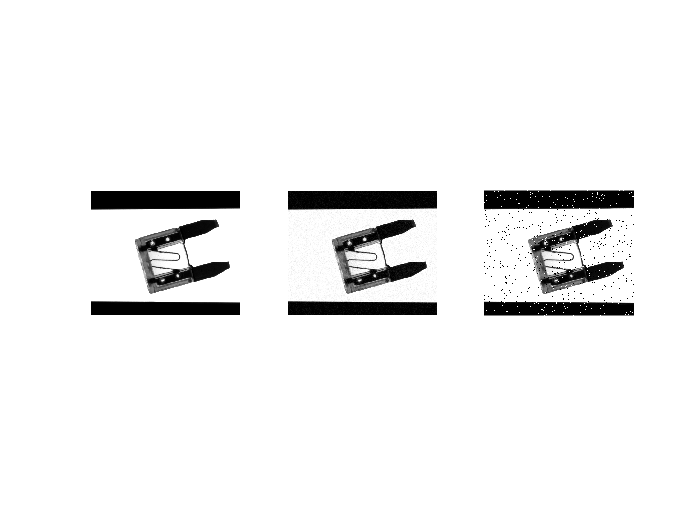

im3 = imread('Fuse 02.tif');
im4 = imnoise(im3, "gaussian", 0, 0.001);
im5 = imnoise(im3, "salt & pepper", 0.05);
figure
subplot(1,3,1); imshow(im3);
subplot(1,3,2); imshow(im4);
subplot(1,3,3); imshow(im5);

#### EJERCICIO 3

Genere un filtro espacial gaussino con desviación típica 2 (tamaño del filtro 11x11) y muéstrelo como una superficie.

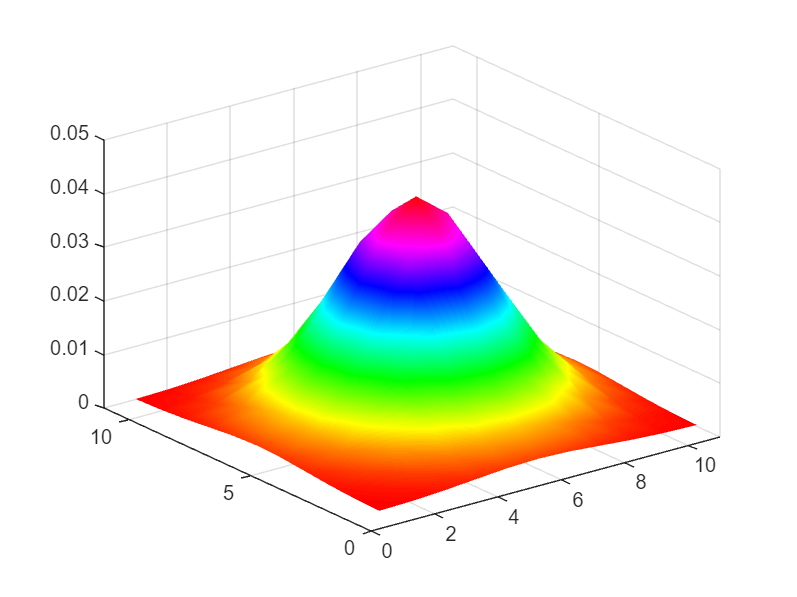

type = 'gaussian'; hsize = 11; sigma=2;
filtro = fspecial (type, hsize, sigma);
figure
surf(double(filtro));
shading interp;
colormap hsv; % gray;

## SUAVIZADO EN EL DOMINIO ESPACIAL

- Media (p. ej., suavizodo utilizando media 11x11

- Media (otra forma de calcularla)

- Mediana

#### EJERCICIO 4

Aplique un filtro de media aritmética en un entorno de 3x3 y 7x7 a las imágenes im4 e im5 y muestre el resultado (im6, im7, im8 e im9), subplot (2,3,…)

m3x3 = ones(3)/(3*3)

m3x3 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


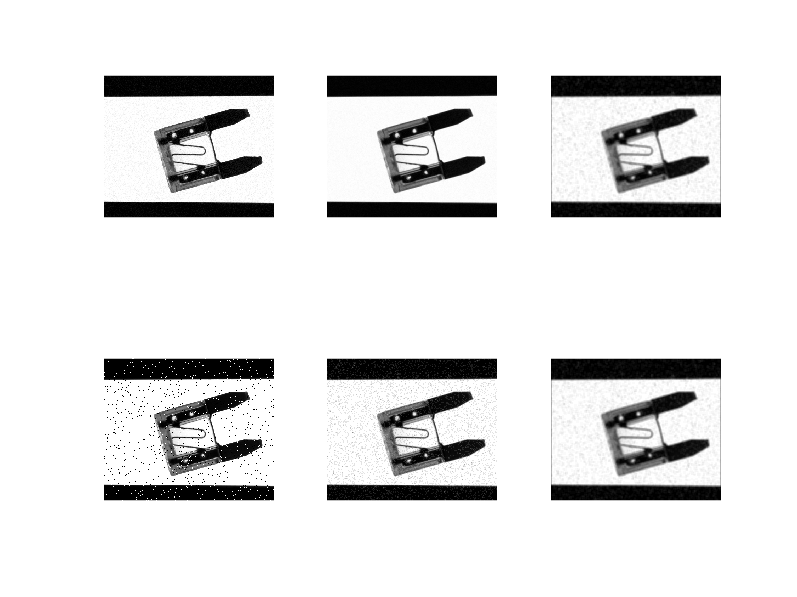

m7x7 = ones(7)/(7*7);

im6 = conv2(im4, m3x3, 'same')/255;
im7 = conv2(im5, m7x7, 'same')/255;
im8 = conv2(im5, fspecial('average', [3, 3]), 'same')/255;
im9 = conv2(im5, fspecial('average', [7, 7]), 'same')/255;

figure
subplot(2,3,1); imshow(im4);
subplot(2,3,2); imshow(im6);
subplot(2,3,3); imshow(im7);

subplot(2,3,4); imshow(im5);
subplot(2,3,5); imshow(im8);
subplot(2,3,6); imshow(im9);

#### EJERCICIO 5

Aplique un filtrado gaussiano a la imagen im4 con la máscara obtenida en el ejercicio 3 y compare el resultado con la aplicación de una máscara de media aritmética de similar dimensión (im10 e im11), muestre también la imagen im4, subplot(1,3,…)

im10=conv2(im4, fspecial('average', [11, 11]), 'same')/255;

Unrecognized function or variable 'im4'.

im11=conv2(im4, filtro, 'same')/255;

figure
subplot(1,3,1); imshow(im4); % ruido Gauss
subplot(1,3,2); imshow(im10); % media 11x11
subplot(1,3,3); imshow(im11); % Gauss 11x11

#### EJERCICIO 6

Aplique un filtro de la mediana a las imágenes im4 e im5 y muestre los resultados (im12 e im13), ,subplot(2,2,…)

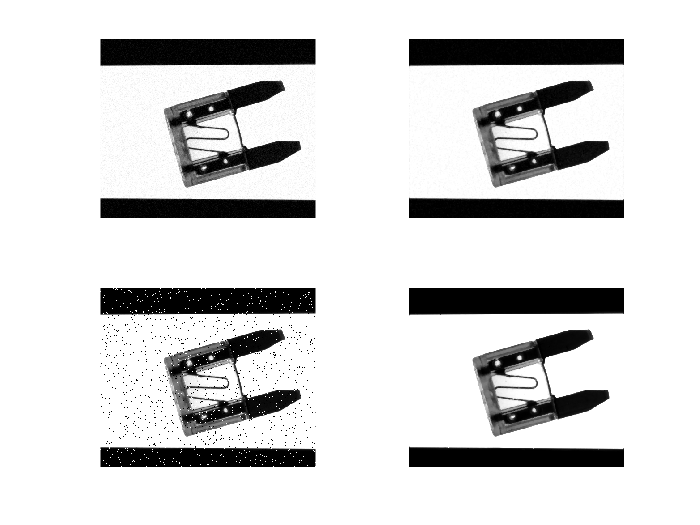

im12 = medfilt2(im4);
im13 = medfilt2(im5);

figure
subplot(2,2,1); imshow(im4);
subplot(2,2,2); imshow(im12);

subplot(2,2,3); imshow(im5);
subplot(2,2,4); imshow(im13);

## SUAVIZADO EN EL DOMINIO FRECUENCIAL

- ILPF (generación de filtro ideal, centrado en el plano imagen)

- BLPF (generación de filtro de Butterworth, centrado en el plano imagen)

#### EJERCICIO 7

Cargue la imagen “Fuse 23.tif” (im14) y muéstrela junto con el espectro de su transformada de Fourier. (suplot(2,1,..))

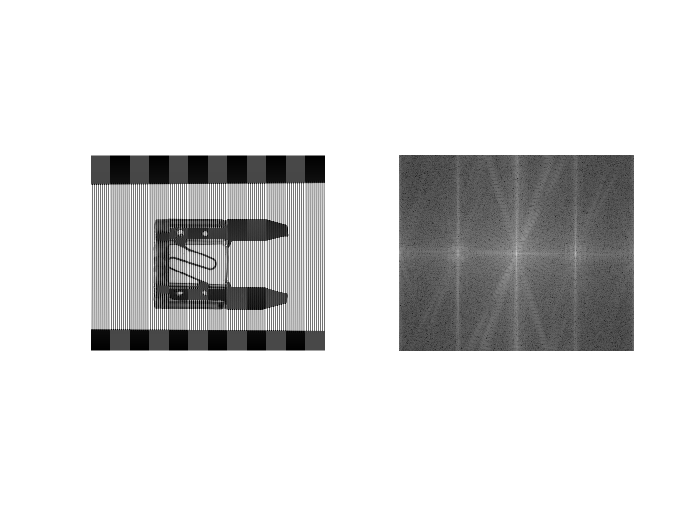

im14 = imread("Fuse 23.tif");
figure
subplot(1,2,1); imshow(im14);
subplot(1,2,2); imshow(30*log10(1+abs(fftshift(fft2(im14))))/255);

#### EJERCICIO 8

Construya los filtros ILPF (d0 = 100) y BLPF (d0 = 50, n=1), para atenuar las frecuencias correspondientes al ruido en la imagen im14. Muestre en una figura estos dos filtros como imágenes, subplot(1,2,…).

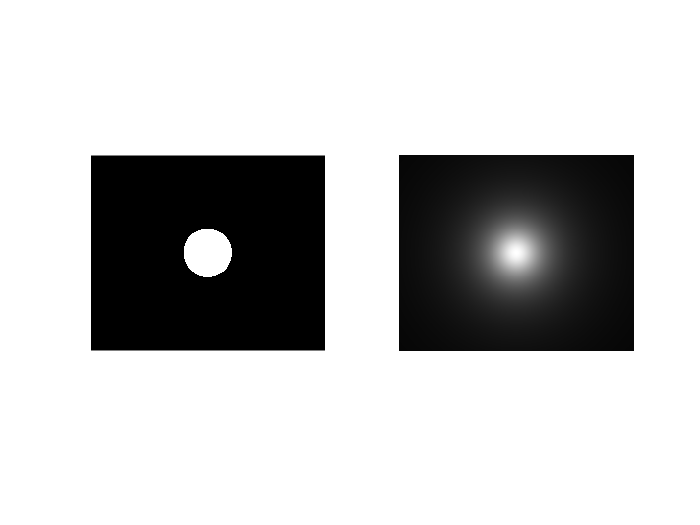

d0 = 50; % frecuencia de corte
n = 1; % orden del filtro;
[tamx,tamy] = size(im14); % Tamaño de la imagen
[xx,yy] = meshgrid(1:tamx,1:tamy);

d = sqrt((xx-tamx/2).^2+(yy-tamy/2).^2); % Distancia al centro
ILPF = (d < d0)';

d = sqrt((xx-tamx/2).^2+(yy-tamy/2).^2); % Distancia al centro
BLPF = (1./(1+(d/d0).^(2*n)))';

figure
subplot(1,2,1); imshow(ILPF);
subplot(1,2,2); imshow(BLPF);

#### EJERCICIO 9

Filtre la imagen im14 con ambos filtros y muestre en una figura la imagen im14, las dos imágenes filtradas (im15 e im16) junto con sus correspondientes espectros de la transformada de Fourier. (subplot(2,3,..)).

NOTA: Debe aplicar estos filtros en el dominio frecuencial, para lo cual deberá calcular la transformada de Fourier de la imagen a filtrar y centrarla en el plano imagen.

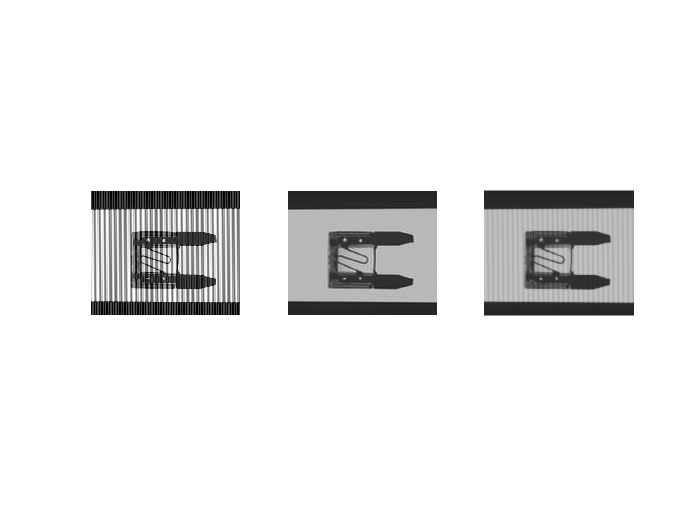

%im14t = fftshift(fft2(im14));
%im15 = real(ifft2(im14t .* ILPF)/255);
%im16 = real(ifft2(im14t .* BLPF))/255;

im14t = fft2(im14);
im15 = real(ifft2(im14t .* fftshift(ILPF))/255);
im16 = real(ifft2(im14t .* fftshift(BLPF))/255);

figure;
subplot(1,3,1); imshow(im14);
subplot(1,3,2); imshow(im15);
subplot(1,3,3); imshow(im16);

## REALCE

- Igualacion de histograma

- Especificacion de histograma

NOTAS

- Si el resultado de histeq no se asigna a una variable de salida, se muestra el resultado de la operación en una figura.

- Si se emplea para especificación de histograma, el histograma especificado como parámetro debe estar normalizado.

#### EJERCICIO 10

Cargue las imágenes “\Meter\Image00.jpg” y “\Meter\Image06.jpg” (im17 e im18) y muéstrelas junto con sus histogramas, suplot (2,2,…).

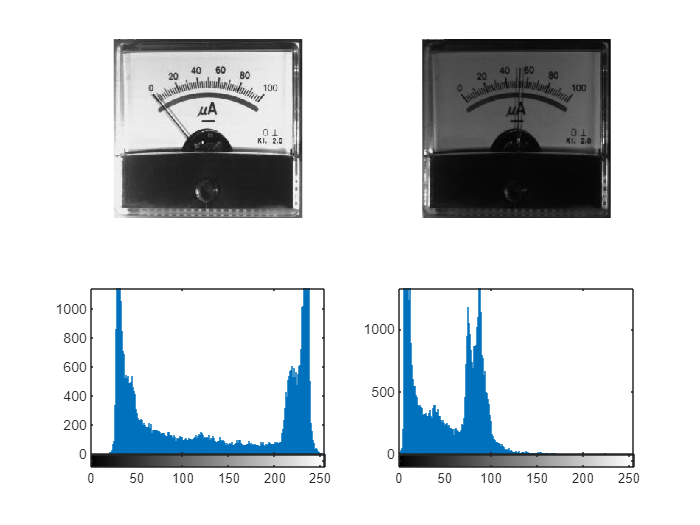

im17 = imread('Image00.jpg');
im18 = imread('Image06.jpg');
figure
subplot(2,2,1); imshow(im17);
subplot(2,2,2); imshow(im18);
subplot(2,2,3); imhist(im17);
subplot(2,2,4); imhist(im18);

#### EJERCICIO 11

Construya la tabla LUT de igualación (lut1) a partir del histograma de la imagen im18 y muéstrela en una figura.

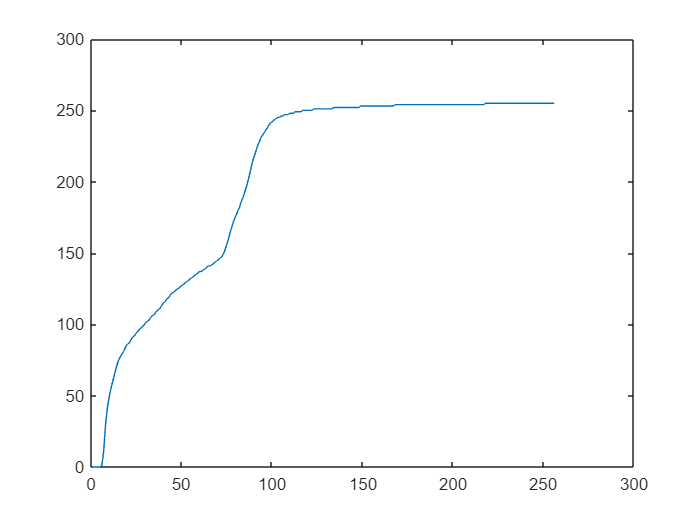

lut1 = uint8 (cumsum(imhist(im18)/numel(im18))*255);
figure; plot(lut1);

#### EJERCICIO 12

Aplique la función lut1 a la imagen im18 para obtener una imagen con histograma igualado (im19) y muestre en una figura las imágenes im18, im19 y sus histogramas, subplot (2,2,…)

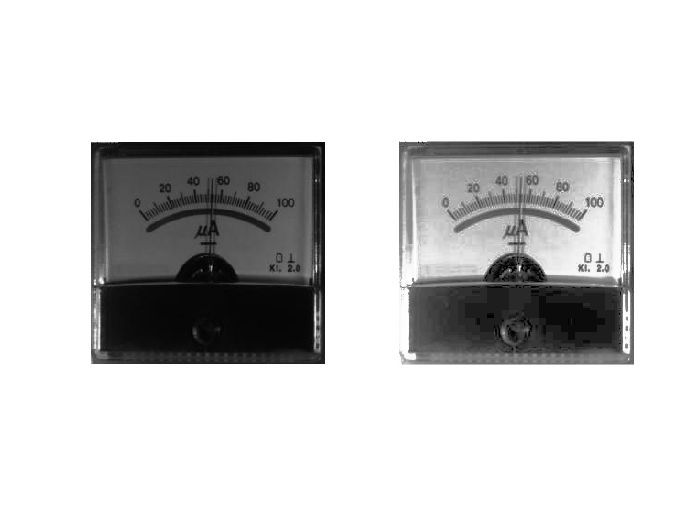

im19 = lut1(im18+1);
figure
subplot(1,2,1); imshow(im18);
subplot(1,2,2); imshow(im19);

#### EJERCICIO 13

Compruebe que el resultado es el mismo que el que se obtiene al aplicar directamente el comando histeq a la imagen im18.

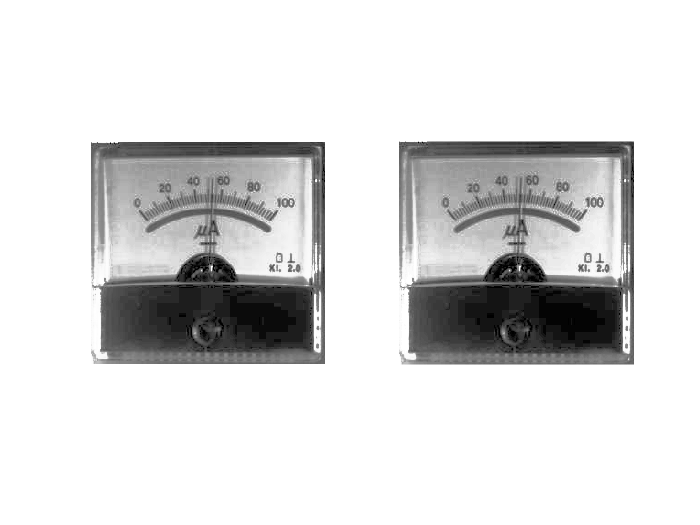

figure;
subplot(1,2,1); imshow(im19);
subplot(1,2,2); histeq(im19);

#### EJERCICIO 14

Aplique un realce a la imagen im18 mediante especificación de histograma (im20), empleando para ello el histograma normalizado de la imagen im17. Muestre en una figura las imágenes im17, im18, im19 e im20 y sus histograma, subplot (2,4,…)

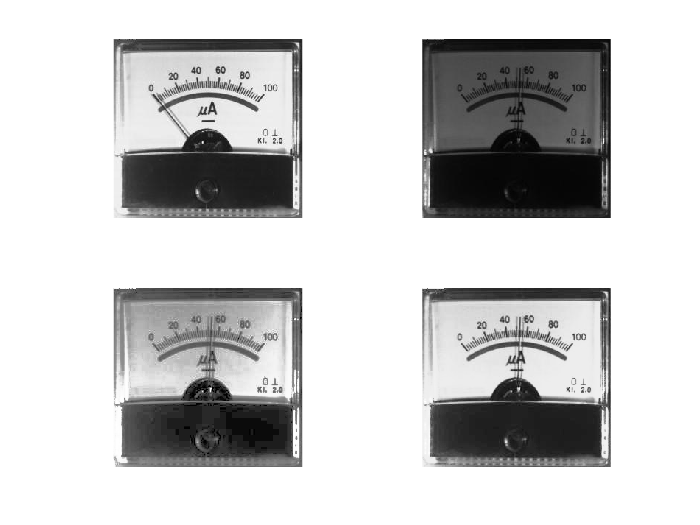

hist_spec = imhist(im17);
lut_spec =  uint8 (cumsum(imhist(im17)/numel(im17))*255);

im20 = histeq(im18, hist_spec);
figure
subplot(2,2,1); imshow(im17); % imagen con buena iluminación
subplot(2,2,2); imshow(im18); % imagen que queremos mejorar / bar(hist_spec);
subplot(2,2,3); imshow(im19); % imagen mejorada con igualación de imágenes / plot(lut_spec);
subplot(2,2,4); imshow(im20); % imagen mejorada con histograma especificado

#### EJERCICIO 15

Aplique un realce a la imagen im15 (resultado de filtrado frecuencial) mediante especificación de histograma y almacene el resultado en im21. Para ello debe emplear histograma normalizado de la imagen im3. Muestre en una figura las imágenes im14, im15, im3 e im21, subplot (2,2,…).

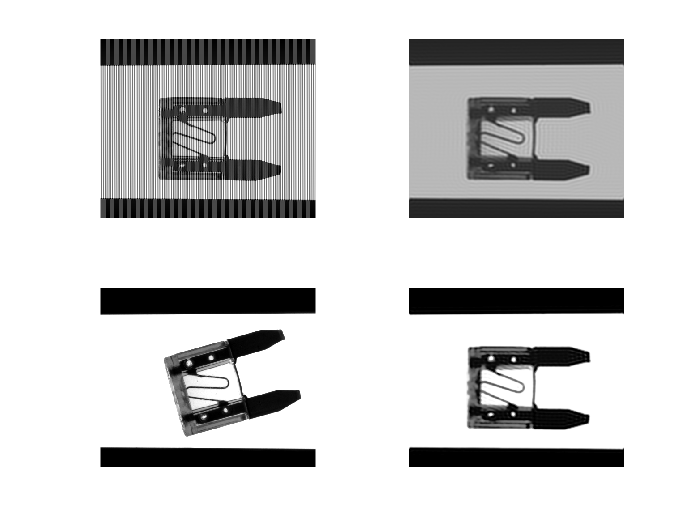

hist_spec = imhist(im3);
im21 = histeq(im15, hist_spec);
figure;
subplot(2,2,1); imshow(im14); % imagen con ruido frecuencial
subplot(2,2,2); imshow(im15); % imagn sin ruido frecuencial
subplot(2,2,3); imshow(im3); % imagen para el cálculo del filtro
subplot(2,2,4); imshow(im21); % después de filtrar y aplicar ecualización